% 3D sphere code
p = 1.225;                                          % Density of the air fluid kg/m3
v1 = 5:5:50;                                        % Free stream Velocities m/s
v2 = 52:2:60;                                        % Free stream Velocities m/s
v = [v1,v2]                                          % Free stream Velocities m/s

v =      5    10    15    20    25    30    35    40    45    50    52    54    56    58    60


u = (1.81*10^-5);                                   %  Flow speed (Velocity) m/s2
c = 0.1;                                            % Sphere diameter m
s = (pi*(c^2))/4                                  % Sphere area m2

s = 0.0079

% Axial force at different measures flow speed
Drag5 = mean([0.061 0.059 0.061 0.064 0.061 0.061 0.061 0.06 0.06 0.06 0.061 0.06 0.061 0.062 0.061 0.062 0.063 0.063 0.064 0.064]);
Drag10 = mean ([0.267 0.269 0.267 0.268 0.263 0.269 0.269 0.264 0.27 0.264 0.27 0.263 0.269 0.268 0.261 0.263 0.252 0.263 0.258 0.258]);
Drag15 = mean ([0.579 0.579 0.565 0.579 0.581 0.577 0.577 0.578 0.58 0.579 0.58 0.576 0.579 0.594 0.594 0.594 0.578 0.594 0.602 0.579]);
Drag20 = mean([1.017 1.017 1.013 1.027 1.021 1.021 1.019 1.024 1.027 1.027 1.032 1.032 1.04 1.04 1.032 1.028 1.03 1.03 1.027 1.034]);
Drag25 = mean ([1.581 1.614 1.62 1.572 1.572 1.572 1.553 1.56 1.583 1.581 1.583 1.567 1.576 1.576 1.565 1.559 1.554 1.548 1.553 1.552]);
Drag30 = mean ([2.336 2.387 2.385 2.37 2.368 2.37 2.338 2.338 2.338 2.288 2.261 2.261 2.287 2.338 2.34 2.289 2.241 2.292 2.291 2.291]);
Drag35 = mean ([3.39 3.39 3.359 3.227 3.359 3.362 3.403 3.403 3.422 3.403 3.408 3.408 3.408 3.379 3.41 3.402 3.376 3.348 3.351 3.302]);
Drag40 = mean ([3.985 4.078 4.091 4.089 4.091 4.087 4.089 4.08 4.081 4.081 4.067 3.977 3.883 3.848 3.837 3.837 3.829 3.809 3.809 3.809]);
Drag45 = mean ([4.923 4.923 4.92 4.913 4.913 4.913 4.937 4.937 4.979 4.97 4.988 4.988 4.988 4.966 4.96 4.96 4.887 4.957 4.964 4.961]);
Drag50 = mean ([5.759 5.796 5.789 5.814 5.837 5.814 5.766 5.758 5.758 5.697 5.712 5.709 5.697 5.644 5.621 5.621 5.622 5.63 5.63 5.63]);
Drag52 = mean ([5.76 5.733 5.733 5.705 5.42 5.424 5.424 5.416 5.403 4.764 4.754 4.754 4.725 4.729 4.72 4.729 4.683 4.708 4.697 4.673]);
Drag54 = mean ([4.726 4.726 4.763 4.759 4.763 4.73 4.726 4.726 4.72 4.73 4.654 4.648 4.687 4.726 4.525 4.525 4.487 4.3 4.339 4.259 4.707]);
Drag56 = mean ([4.354 4.313 4.325 4.325 4.396 4.464 4.396 4.333 4.39 4.39 4.396 4.333 4.333 4.396 4.665 4.716 4.715 4.653 4.703 4.653]);
Drag58 = mean ([2.32 2.315 2.425 2.425 2.388 2.394 2.422 2.435 2.435 2.402 2.402 2.414 2.408 2.404 2.232 2.201 2.232 2.231 2.277 2.191]);
Drag60 = mean ([1.917 1.645 1.645 1.702 1.702 1.645 1.701 1.752 1.752 1.695 1.752 1.718 1.695 1.661 1.739 1.683 1.551 1.752 2.144 1.655]);
Drag = [Drag5, Drag10, Drag15, Drag20, Drag25, Drag30, Drag35, Drag40, Drag45, Drag50, Drag52, Drag54, Drag56, Drag58, Drag60] % Measured drag

Drag =     0.0615    0.2647    0.5822    1.0269    1.5720    2.3204    3.3755    3.9728    4.9473    5.7152    5.0977    4.6298    4.4625    2.3477    1.7253


 
CD = (2*Drag)./(p*s*(v.^2))                         % Drag coefficient

CD =     0.5110    0.5504    0.5379    0.5337    0.5229    0.5360    0.5728    0.5162    0.5079    0.4752    0.3919    0.3300    0.2958    0.1451    0.0996


Re = (v*p*c)/u                                     %  Reynolds number

Re = 	1.0e+05 *

    0.3384    0.6768    1.0152    1.3536    1.6920    2.0304    2.3688    2.7072    3.0456    3.3840    3.5193    3.6547    3.7901    3.9254    4.0608



% To find the Critical measured Reynolds number at CD = 0.3
i = figure('Visible','off');
plot (Re,CD, 'g','lineWidth',1);
LineH = get(gca, 'Children');
CDe = get(LineH, 'XData');
Ree = get(LineH, 'YData');
xx = 0.3;  % Any value
Recr =  interp1(Ree, CDe, xx);                                    % Critical measured reynolds number
disp (['Critical Reynolds number = ' num2str(Recr) ])

Critical Reynolds number = 377346.3902


T = 1.25*(385000/Recr)-1.25                          % Turbulence level %

T = 0.0254

Velocity = (Recr * u)/(p*c)                          % Critical velocity m/s2

Velocity = 55.7549

  
% To calculate corrected value
CS = 0.305*0.305;                                    % Cross sectional area of wind tunnel test section m2
sb =0.809*((s/CS)^1.5);                               % Solid blockage factor
wb = (1/4)*CD*(s/CS);                               % Wake blockade factor
b = sb + wb;                                       % Total Blockage factor

vc = v.*(1+b)                                    % Corrected speed

vc =     5.1532   10.3146   15.4680   20.6222   25.7721   30.9348   36.1178   41.2296   46.3755   51.4939   53.4622   55.4479   57.4610   59.3287   61.3170


Rec = (vc*p*c)/u                                 % Corrected Reyonlds number

Rec = 	1.0e+05 *

    0.3488    0.6981    1.0469    1.3957    1.7442    2.0937    2.4444    2.7904    3.1387    3.4851    3.6183    3.7527    3.8889    4.0153    4.1499


CDc = (2*Drag)./(p*s*(vc.^2))                    %  Corrected Drag coefficient

CDc =     0.4810    0.5173    0.5058    0.5020    0.4920    0.5041    0.5379    0.4858    0.4782    0.4480    0.3708    0.3130    0.2810    0.1386    0.0954




% To find the Critical corrected Reynolds number at CD = 0.3
j = plot (Rec,CDc, 'b'); 
LineG = get(gca, 'Children');
CDec = get(LineG, 'XData');
Reec = get(LineG, 'YData');
x = 0.3;  % Any value
Recrc = interp1(Reec, CDec, xx);                             % Critical corrected reynolds number
disp (['Critical Reynolds number = ' num2str(Recrc) ])

Critical Reynolds number = 380805.1178


Tc = 1.25*(385000/Recrc)-1.25                          % Turbulence level %

Tc = 0.0138

Velocityc = (Recrc * u)/(p*c)                         % Critical velocity m/s2

Velocityc = 56.2659

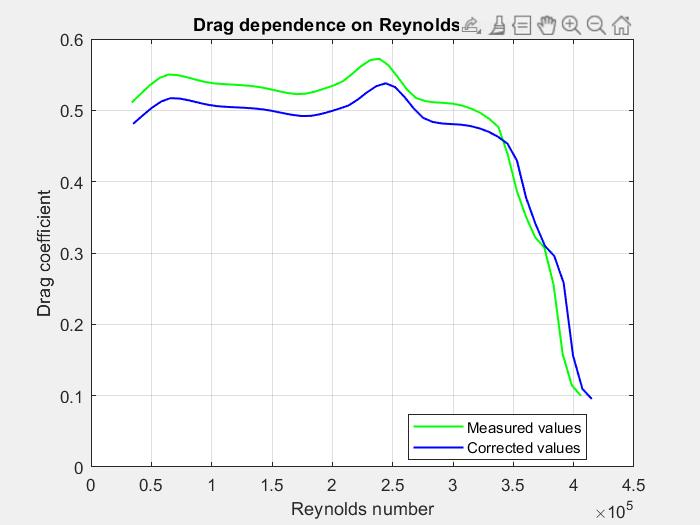


xi=linspace(min(Re), max(Re), 50);
xj=linspace(min(Rec), max(Rec), 50);
yi=interp1(Re,CD,xi,'makima');
yj=interp1(Rec,CDc,xj,'makima');

k = figure('Visible','on');
plot(xi,yi,'g',xj,yj,'b','linewidth',1.2)
title('Drag dependence on Reynolds number')
xlabel('Reynolds number');
ylabel('Drag coefficient');
legend({'Measured values';'Corrected values'},'Location','best');
grid on


% 2D cylinder code
 
vel = 25;
Patm = 101400;                                      % Atmpsoheric pressure Pa
Pwindym = 378;                                      % Wind tunnel dynamic pressure Pa
P0s = Patm - Pwindym;                               % Static pressure inside wind tunnel Pa
Pdym = 0.5*p*(vel^2);                                 % Bernoulli's equation to determine Dynamic pressure Pa                
P = 1000;                                           %  density of the liquid manometer fluid kg/m3
g = 9.81;                                           %  Gravitational force m/s2

deg = 0:15:345;                                     % Position (°) 
Rey = (vel*p*c)/u                                     %  Reynolds number of cylinder

Rey = 1.6920e+05

%  Liquid height of pitot tube connected to the clean cylinder
H1 = [0, 0.5, 1.7 3.4, 4.6, 4.6, 4.3, 4.2, 4.2, 4.2, 4.2, 4.2, 4.2, 4.4, 4.4, 4.4, 4.3, 4.4, 4.5, 4.6, 4.6, 3.1, 1.6, 0.5] * 0.0254;   
Ps1 = (Patm - (P*g*H1))                            % Static pressure on airfoil surface

Ps1 = 	1.0e+05 *

    1.0140    1.0128    1.0098    1.0055    1.0025    1.0025    1.0033    1.0035    1.0035    1.0035    1.0035    1.0035    1.0035    1.0030    1.0030    1.0030    1.0033    1.0030    1.0028    1.0025    1.0025    1.0063    1.0100    1.0128


C1P = (Ps1-P0s)/Pwindym                                % pressure coefficient Pa

C1P =     1.0000    0.6704   -0.1206   -1.2412   -2.0323   -2.0323   -1.8345   -1.7686   -1.7686   -1.7686   -1.7686   -1.7686   -1.7686   -1.9004   -1.9004   -1.9004   -1.8345   -1.9004   -1.9664   -2.0323   -2.0323   -1.0435   -0.0547    0.6704


%  Liquid height of pitot tube connected to the dirty  cylinder
H2 = [0, 0.3, 1.5, 2.6, 6.4, 5.8, 6.2, 5.1, 4.1, 4.1, 4.1, 4.1, 4.1, 4.1, 4.1, 4.1, 4.1, 4.4, 5.6, 5.7, 6.7, 2.7, 1.8, 0.5] * 0.0254; %manometer height for clean cylinder
Ps2 = (Patm - (P*g*H2))                            % Static pressure on airfoil surface

Ps2 = 	1.0e+05 *

    1.0140    1.0133    1.0103    1.0075    0.9981    0.9995    0.9986    1.0013    1.0038    1.0038    1.0038    1.0038    1.0038    1.0038    1.0038    1.0038    1.0038    1.0030    1.0000    0.9998    0.9973    1.0073    1.0095    1.0128


C2P = (Ps2-P0s)/Pwindym                                % pressure coefficient Pa

C2P =     1.0000    0.8022    0.0112   -0.7139   -3.2188   -2.8233   -3.0870   -2.3619   -1.7027   -1.7027   -1.7027   -1.7027   -1.7027   -1.7027   -1.7027   -1.7027   -1.7027   -1.9004   -2.6915   -2.7574   -3.4166   -0.7798   -0.1865    0.6704


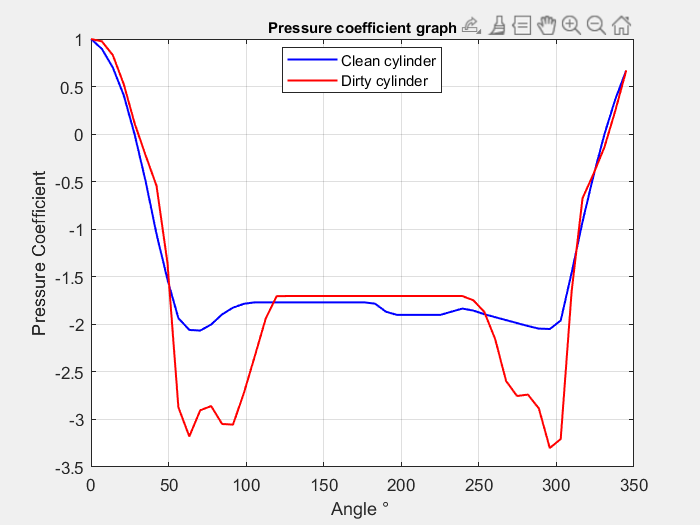

 
x1=linspace(min(deg), max(deg), 50);
y1=interp1(deg,C1P,x1,'makima');
y2=interp1(deg,C2P,x1,'makima');

l = figure('Visible','on');
plot(x1,y1,'b',x1,y2,'r','linewidth',1.2)
title('Pressure coefficient graph','FontSize',9);    % use for title positioning
xlabel('Angle ° ');
ylabel('Pressure Coefficient');
legend({'Clean cylinder';'Dirty cylinder'},'Location','best');
grid on